% Test For seventh sound

% Sound captured in mumbai market.
% Length :- 29 sec
% Reading the audio
[samples, fsample] = audioread('TestAudio7.wav');

player = audioplayer(samples, fsample);
play(player);


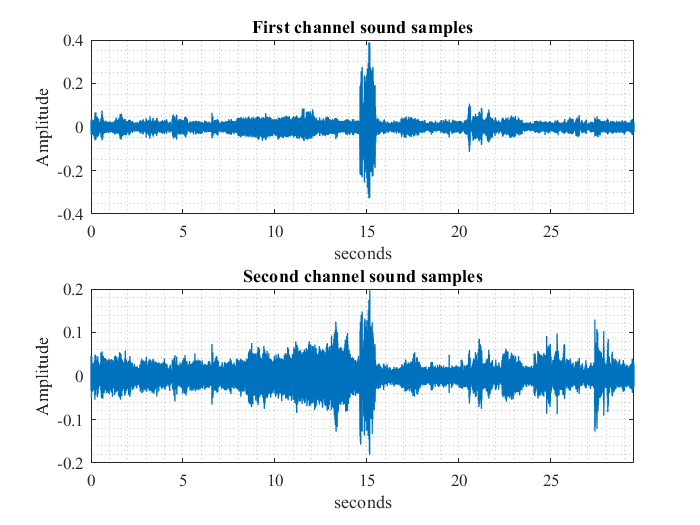

% Evidence handling and Initial assessment

% Waveform view
ShowWaveform(samples, fsample);

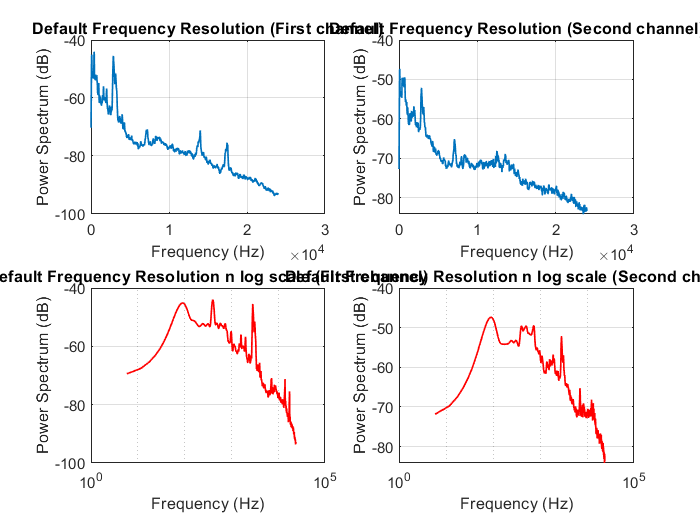


% PSD view
ShowPSD2(samples, fsample);


% Spectrogram view
% ShowSpectrogram(samples, fsample);
% Because it is too large size audio recording hence, spectrogram would
% take too much time

% Statistical view
audioStats(samples, fsample);

Max value in first Channel = 0.38922
Max value in second Channel = 0.19986
Minimum value in first Channel = -0.32739
Minimum value in second Channel = -0.18192
Mean value in first channel = -3.2807e-06
Mean value in second channel= -3.147e-06
standard deviation of first channel= 0.017072
standard deviation of second channel= 0.014982
Variance of first channel= 0.00029145
Variance of second channel= 0.00022447
Power in first channel in dB= -35.3544
Power in second channel in dB= -36.4884
Sampling frequency in Hz =48000


% Audio feactures (MFCC)

% Mel Frequency capstral coefficient

[coeff, delta, deltaDelta, logf] = mfcc(samples, fsample);



% Audio Enhancement techniques

% bandpass filter 
order =256;
level =0.5

level = 0.5000

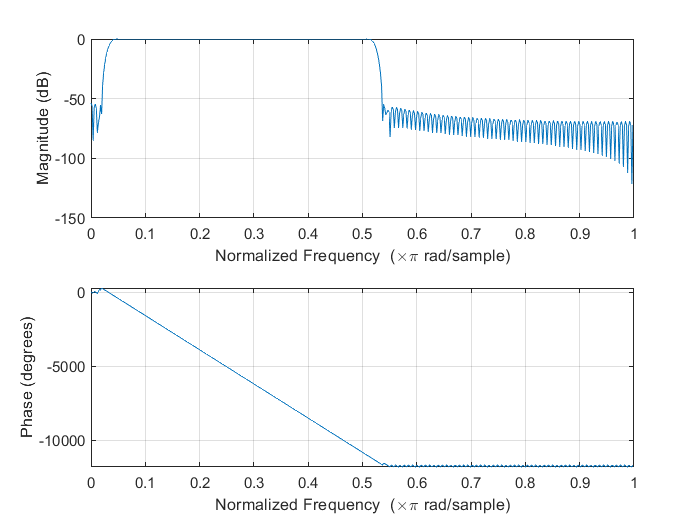

resultAudio = bandpassVocalFilter(samples, order,fsample, level);

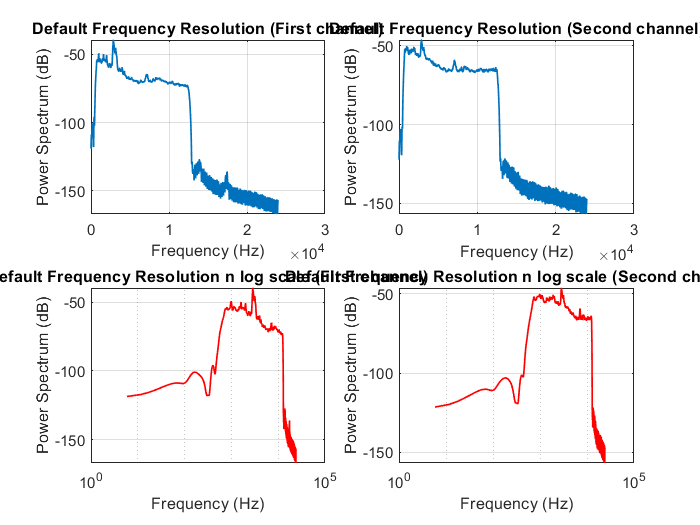


player = audioplayer(resultAudio, fsample);
play(player);

ShowPSD2(resultAudio, fsample);

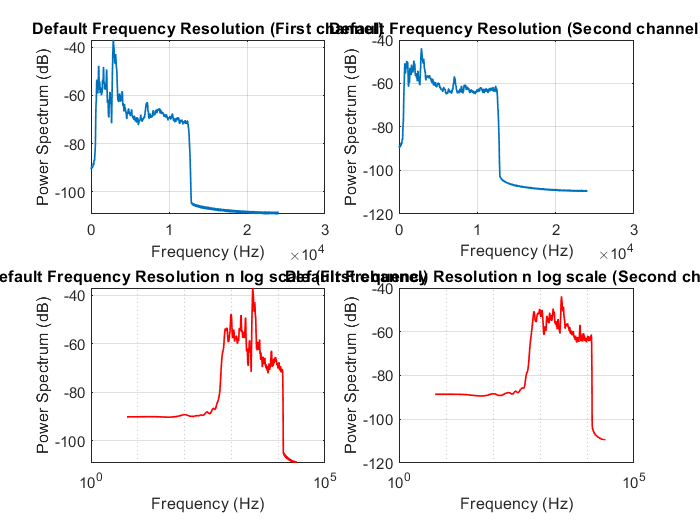


% Wiener filter approach

resultAudio2 = wienerFilter(resultAudio, fsample, 0.5);

player = audioplayer(resultAudio2, fsample);
play(player);

ShowPSD2(resultAudio2, fsample);

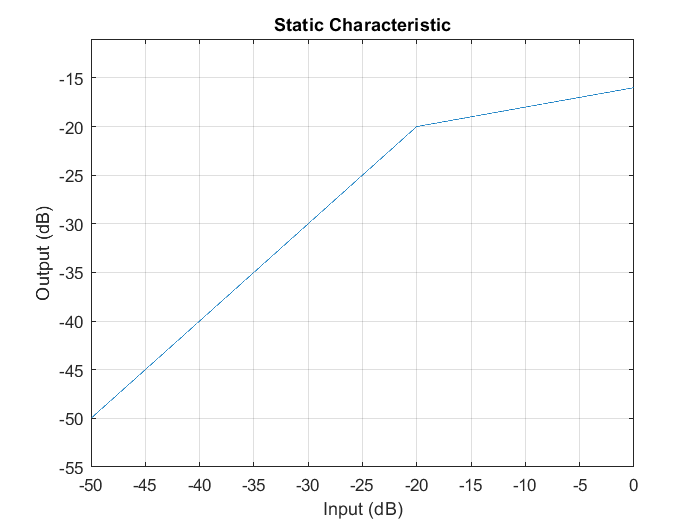

% Compressor 

dRC = compressor(-20,5,'SampleRate',fsample);
visualize(dRC)

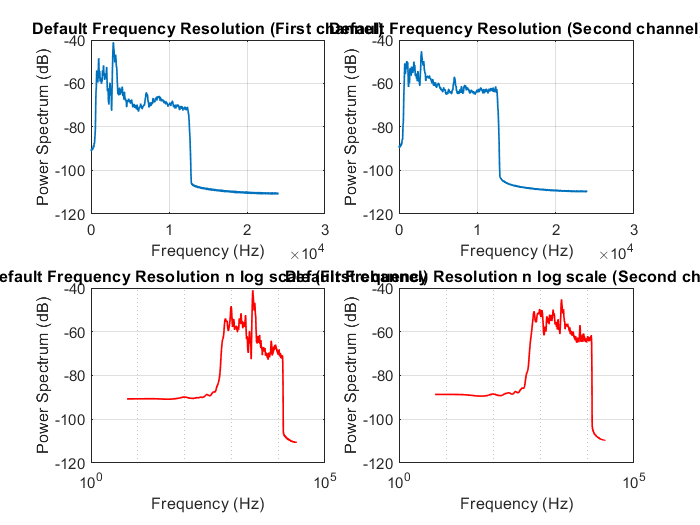


resultAudio3 = dRC(resultAudio2);

player = audioplayer(resultAudio3, fsample);
play(player);

ShowPSD2(resultAudio3, fsample);

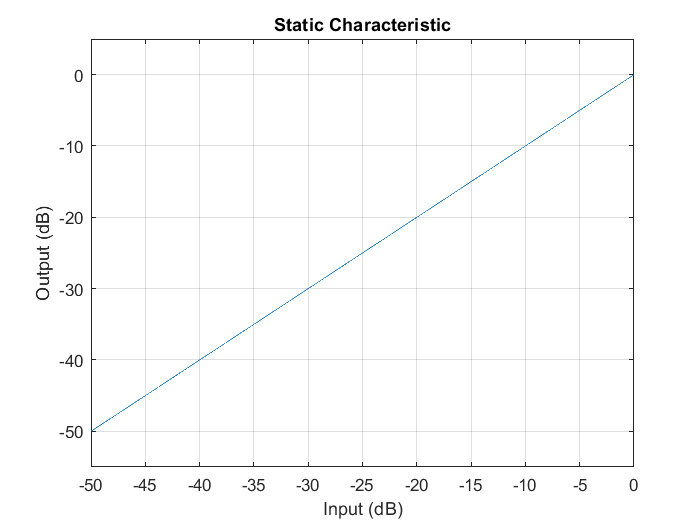

% Expender

dRC = expander(-80, 5, 'SampleRate',fsample);
visualize(dRC);

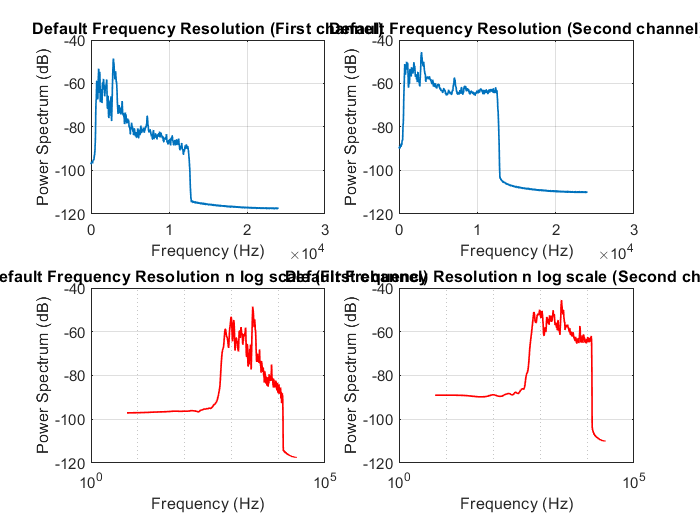


resultAudio4 = dRC(resultAudio3);


player = audioplayer(resultAudio4, fsample);
play(player);

ShowPSD2(resultAudio4, fsample);

audiowrite('enhancedTestAudio7.wav', resultAudio3, fsample)


